%{
ES115 Engineering Computer Applications 
Module 1 Project: Streetlight Brightness Model

Author: Luis A. Lamas Carreto
Instructor: Lynroy Grant
Date: April 26, 2026

Purpose:
The purpose of this project is to model and compare the light distribution of two 
streetlights using quadratic functions. By using MATLAB to analyze peak intensities 
and intersection points, we can determine the coverage of each light and identify 
where the illumination from both sources is equal.

Inputs:
- Position Range (x): -20 to 20 meters
- Model Parameters: Peak brightness (B_{max}), location (h), and decay rate (k)

Outputs:
- Brightness Vectors (B_1, B_2)
- Peak brightness locations and magnitudes
- Approximate intersection location (x where (B_1 approx B_2)

Engineering Workflows:
- Spatial Modeling: Representing physical intensity through vertex-form equations
- Comparative Analysis: Evaluating hardware performance across a distance
- Root Analysis: Finding the intersection of two independent models

MATLAB Tools:
- Vector Operations: Evaluating functions across a discrete range
- max(): Pinpointing peak values and indices
- min(abs()): Identifying the point of minimum difference between vectors
- plot(): Graphing spatial data for visual assessment
%}


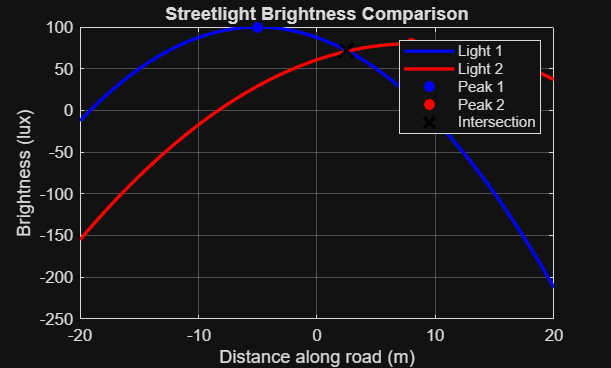

x = -20:0.5:20;

% Streetlight 1 parameters
h1 = -5; Bmax1 = 100; k1 = 0.5;
B1 = -k1*(x - h1).^2 + Bmax1;

% Streetlight 2 parameters
h2 = 8; Bmax2 = 80; k2 = 0.3;
B2 = -k2*(x - h2).^2 + Bmax2;

% Identify maximums
[val1, idx1] = max(B1);
[val2, idx2] = max(B2);

% Find approximate intersection
intersect_idx = find(abs(B1 - B2) == min(abs(B1 - B2)));
x_intersect = x(intersect_idx);

% Visualization
figure;
plot(x, B1, 'b', 'LineWidth', 2); hold on;
plot(x, B2, 'r', 'LineWidth', 2);
plot(x(idx1), val1, 'bo', 'MarkerFaceColor', 'b');
plot(x(idx2), val2, 'ro', 'MarkerFaceColor', 'r');
plot(x_intersect, B1(intersect_idx), 'kx', 'MarkerSize', 12, 'LineWidth', 2);
grid on;
xlabel('Distance along road (m)');
ylabel('Brightness (lux)');
title('Streetlight Brightness Comparison');
legend('Light 1', 'Light 2', 'Peak 1', 'Peak 2', 'Intersection');


% Report
fprintf('Light 1 Max: %.2f lux at %.1f m\n', val1, x(idx1));

Light 1 Max: 100.00 lux at -5.0 m


fprintf('Light 2 Max: %.2f lux at %.1f m\n', val2, x(idx2));

Light 2 Max: 80.00 lux at 8.0 m


fprintf('Approximate Intersection at: %.2f m\n', x_intersect);

Approximate Intersection at: 2.50 m
